UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

# *Laboratory 8: Curve Fitting*

## **Name: Juan Camilo Jaimes Ávila**

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab8_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab8_name_lastname.rar*** and subject **Analisis_Lab8_name** to **jbacquin@uis.edu.co.**

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To implement the least-squares method in Matlab. 

- To interpret problems which can be solved by the least-squares method.

## **Practice:**

### **Implementing **

- **Exercise 1 (1.5 points).** Create a Matlab function called *my_lsline_name_lastname()* to construct the least-squares line $y=\textrm{Ax}+B$ that fits the $N$data points $\left(x_k ,y_k \right)$ with $k\in \left\lbrace 1,\ldotp \ldotp \ldotp N\right\rbrace$. Then, use the created function to find the least-squares line $y=f\left(x\right)=\textrm{Ax}+B$ for the data and calculate $E_2 \left(f\right)$ (like mean squared error or mean absolute error).

#### 
$$\text{MSE} = \frac{1}{n} \sum_{i=1}^{n} (Y_i - \hat{Y}_i)^2$$
            
$$\text{MAE} = \frac{1}{n} \sum_{i=1}^{n} |Y_i - \hat{Y}_i|
$$


% Given data points
x = [-8, -2, 0, 4, 6];
y = [6.8, 5.0, 2.2, 0.5, -1.3];

% Call the least-squares function to find A and B
[A, B] = my_lsline_juan_jaimes(x, y);

% Display the least-squares line equation
fprintf('Least-Squares Line: y = %.4fx + %.4f\n', A, B);

Least-Squares Line: y = -0.5850x + 2.6400



% Compute the fitted values (predictions) using the least-squares line
y_hat = A * x + B;

% Calculate Mean Squared Error (MSE)
MSE = mean((y - y_hat).^2);

% Calculate Mean Absolute Error (MAE)
MAE = mean(abs(y - y_hat));

% Display the errors
fprintf('Mean Squared Error (MSE): %.4f\n', MSE);

Mean Squared Error (MSE): 0.4210


fprintf('Mean Absolute Error (MAE): %.4f\n', MAE);

Mean Absolute Error (MAE): 0.5560


- **Exercise 2 (1 point).** Plot the least-squares line and the given points from before item. Discuss what you observe.

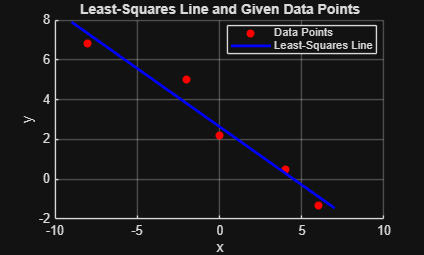

% Create a range of x values for plotting the line
x_line = linspace(min(x) - 1, max(x) + 1, 100); % Generate 100 points for a smooth line

% Calculate the corresponding y values for the least-squares line
y_line = A * x_line + B;

% Create the plot
figure;

% Plot the given data points
scatter(x, y, 'filled', 'MarkerFaceColor', 'r');
hold on; % Keep the data points on the plot

% Plot the least-squares line
plot(x_line, y_line, 'b-', 'LineWidth', 2);

% Label the axes
xlabel('x');
ylabel('y');

% Title for the plot
title('Least-Squares Line and Given Data Points');

% Add a legend
legend('Data Points', 'Least-Squares Line', 'Location', 'best');

% Display the plot
grid on;
hold off; % Release the hold on the plot

            **Conclusion: **The least-squares method assumes a linear relationship between x and y. While this line provides the best linear fit, it may not fully capture any non-         linear trends that might be present in the data. You can see that the line does not pass exactly through any of the points (except possibly for special cases), but it minimizes the overall squared errors between the points and the line. If the errors are small, the line is a good approximation of the data's trend.We can see points are far from the line, they are considered outliers.

**Interpreting**

Kepler’s laws of planetary motion describe the motions of the planets in the solar system. Specifically, the third Kepler’s law establishes the square of the orbital period of a planet is directly proportional to the cube of the semi-major axis of its orbit. This law captures the relationship between the distance of planets from the Sun, and their orbital periods. Then,

$T^2 =CR^3$,  (1)

where $T$ is the orbital period, $R$ is the semi-major axis of its orbit, and $C$ is the Kepler’s constant. Here, $C$ is given by

$C=\frac{4\pi^2 }{\mathrm{GM}}$ ,  (2)

where $M=1\ldotp 989\times {10}^{30}$ [$\mathrm{Kg}$] is the mass of the Sun and $G=6\ldotp 674\times {10}^{-11}$ [$Nm^2$/ ${\textrm{Kg}}^2$] is the universal gravitational constant.

*Table 1: Planetary data: orbital parameters. ****Note that the Semi-major axis values are x10^6***

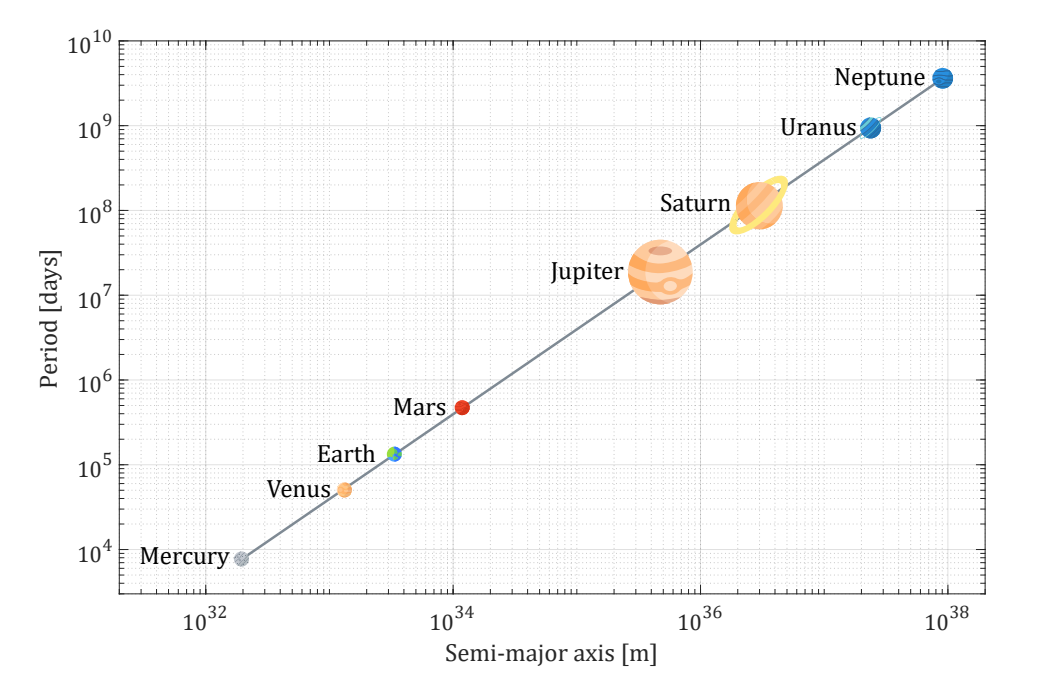

*Figure 1: Relationship between the orbital periods of planets and the distance of planets from the Sun in a log-log plot.*

- **Exercise 3 (1 point).** Use the created function to find the least-squares line $y=\mathrm{Ax}+B$ for the planetary data, as shown in Table 1, considering

$\log_{10} \left(T^2 \right)=\log_{10} \left(R^3 \right)+\log_{10} \left(C\right)$,  (3)

             where $y=\log_{10} \left(T^2 \right)\;,x=\log_{10} \left(R^3 \right)\;,B=\log_{10} \left(C\right)\;\mathrm{and}\;A=1\ldotp$

% Data for the planets (orbital period in days and semi-major axis in million km)
planets = {
    'Mercury', 87.97, 57.91;
    'Venus', 224.70, 108.70;
    'Earth', 365.26, 149.60;
    'Mars', 686.98, 227.92;
    'Jupiter', 4332.59, 778.57;
    'Saturn', 10759.22, 1433.53;
    'Uranus', 30685.40, 2872.46;
    'Neptune', 60189.00, 4495.06
};

% Extract periods (T) and semi-major axes (R)
T = cell2mat(planets(:, 2)); % Orbital period in days
R = cell2mat(planets(:, 3)) * 1e6; % Semi-major axis in meters (converted from million km)

% Compute x and y
x = log10(R.^3); % x = log10(R^3)
y = log10(T.^2); % y = log10(T^2)

% Use the least-squares function to find A and B
[A, B] = my_lsline_juan_jaimes(x, y); 

% Compute the constant C
C = 10^B;

% Display the results
fprintf('Least-Squares Line: y = %.4fx + %.4f\n', A, B);

Least-Squares Line: y = 1.0000x + -19.4017


fprintf('Keplers constant C = %.4e\n', C);

Keplers constant C = 3.9655e-20


-  **Exercise 4 (1 point). **Construct a sketch similar to illustrate in Fig. 1 from the least-squares line computed previously.

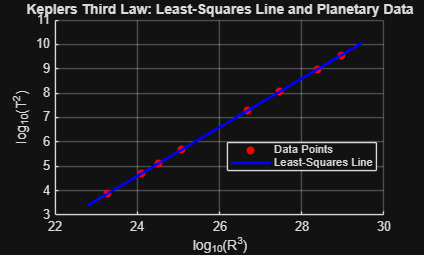

% Create the plot (sketch)
figure;

% Plot the transformed data points
scatter(x, y, 'filled', 'MarkerFaceColor', 'r');
hold on; % Keep the data points on the plot

% Plot the least-squares line
x_line = linspace(min(x)-0.5, max(x)+0.5, 100); % Generate x values for a smooth line
y_line = A * x_line + B; % Calculate the corresponding y values for the least-squares line
plot(x_line, y_line, 'b-', 'LineWidth', 2);

% Label the axes
xlabel('log_{10}(R^3)');
ylabel('log_{10}(T^2)');

% Title for the plot
title('Keplers Third Law: Least-Squares Line and Planetary Data');

% Add a legend
legend('Data Points', 'Least-Squares Line', 'Location', 'best');

% Display the plot
grid on;
hold off; % Release the hold on the plot

- **Exercise 5 (0.5 points).** Find an approximation of the universal gravitational constant $G$ through the least-squares line computed previously. Compare the estimated gravitational constant regarding the theoretical value using relative error. Hint. Use $C={10}^B \;$and formula (2). *Be careful with the units.* 

% Given mass of the Sun and theoretical value of G
M_sun = 1.989e30; % kg (mass of the Sun)
G_theoretical = 6.674e-11; % N·m^2/kg^2 (theoretical value of the gravitational constant)

% Using the previously calculated B (from the least-squares line)
C = 10^B; % Kepler's constant from the intercept of the least-squares line

% Estimate G using the formula G = (4 * pi^2) / (C * M)
G_estimated = (4 * pi^2) / (C * M_sun);

% Calculate the relative error
relative_error = abs((G_estimated - G_theoretical) / G_theoretical);

% Display the results
fprintf('Estimated Gravitational Constant G: %.4e N·m^2/kg^2\n', G_estimated);

Estimated Gravitational Constant G: 5.0052e-10 N·m^2/kg^2


fprintf('Theoretical Gravitational Constant G: %.4e N·m^2/kg^2\n', G_theoretical);

Theoretical Gravitational Constant G: 6.6740e-11 N·m^2/kg^2


fprintf('Relative Error: %.4f\n', relative_error);

Relative Error: 6.4996
